# Create a Multilevel List One List at a Time

You can create each sublist as an `mlreportgen.dom.OrderedList` or `mlreportgen.dom.UnorderedList` object and then append the sublist to the top-level list.

 This example appends an unordered sublist to an ordered top-level list.

import mlreportgen.dom.*;
d = Document('orderedListReport','html');

ol = OrderedList({'Start MATLAB', ...
     'Create a rank 3 or 4 magic square:'});
 
optionList = UnorderedList;
li = ListItem('>> magic(3)');
table = append(li,Table(magic(3)));
table.Width = '1in';
append(optionList, li);
li = ListItem('>> magic(4)');
table = append(li,Table(magic(4)));
table.Width = '1in';
append(optionList,li);
append(ol, optionList);

append(ol, ListItem('Close MATLAB')); 
append(d,ol);

close(d);
rptview('orderedListReport','html');

Here is the generated list:

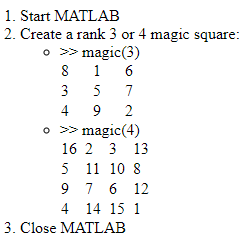

*Copyright 2019 The MathWorks, Inc.*